# Equilibria in Truss Beams

Instructions are in the task pane to the left. Complete and submit each task one at a time.

A = [-sind(30) -sind(30) 0 0 0 0 0 0 0;...
    -cosd(30) cosd(30) 0 0 0 0 0 0 0; ...
    sind(30) 0 0 -sind(60) -sind(60) 0 0 0 0;...
    cosd(30) 0 1 -cosd(60) cosd(60) 0 0 0 0;...
    0 sind(30) 0 0 0 -sind(60) -sind(60) 0 0;...
    0 -cosd(30) -1 0 0 -cosd(60) cosd(60) 0 0;...
    0 0 0 0 sind(60) sind(60) 0 0 0;...
    0 0 0 0 -cosd(60) cosd(60) 0 -1 1;...
    0 0 0 0 0 0 -cosd(60) 0 -1]

A =    -0.5000   -0.5000         0         0         0         0         0         0         0
   -0.8660    0.8660         0         0         0         0         0         0         0
    0.5000         0         0   -0.8660   -0.8660         0         0         0         0
    0.8660         0    1.0000   -0.5000    0.5000         0         0         0         0
         0    0.5000         0         0         0   -0.8660   -0.8660         0         0
         0   -0.8660   -1.0000         0         0   -0.5000    0.5000         0         0
         0         0         0         0    0.8660    0.8660         0         0         0
         0         0         0         0   -0.5000    0.5000         0   -1.0000    1.0000
         0         0         0         0         0         0   -0.5000         0   -1.0000


## Task 1

A 9x9 matrix of force coefficients has been created for you. 

Task

Use the following steps to solve for the forces in each beam of the truss:

- Create a column vector containing the external forces.

- Solve the system of equations for the unknown force vector. 

- Pass the force vector to the `plotTruss` local function, which has been created specifically for this activity.

b=[10000 0 10000 0 10000 0 0 0 0]'

b =        10000
           0
       10000
           0
       10000
           0
           0
           0
           0


F=A\b

F = 1.0e+04 *

   -1.0000
   -1.0000
         0
   -1.7321
   -0.0000
    0.0000
   -1.7321
    0.8660
    0.8660


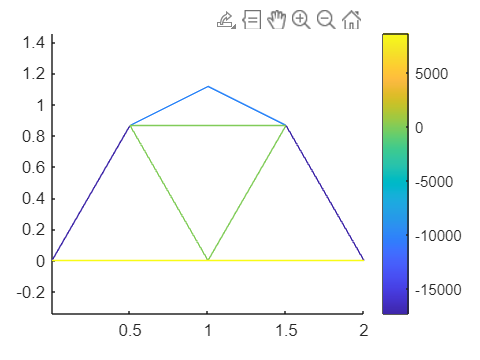

plotTruss(F)

## Further Practice

You might notice there are both positive and negative forces in the  force vector. Here, positive forces represent beams that are in tension, meaning the forces pulls inward along the beam, whereas negative forces indicate beams that are in compression. meaning the forces pushing  outwards along the beam. 

Interestingly, the middle beams have no compression or tension forces applied to them.

function plotTruss(f)

%Joint Locations
x = [0 0.5 1 1 1.5 2];
y = [0 sind(60) (sind(60)+0.5*sind(30)) 0 sind(60) 0];

%Rescale forces to be between 1 and 255
fScale = round(rescale(f,0,255))+1;
cmap = colormap("parula");

%Plot Beams
hold on
line([x(2) x(3)],[y(2) y(3)],"Color",cmap(fScale(1),:))
line([x(4) x(5)],[y(3) y(2)],"Color",cmap(fScale(2),:))
line([x(2) x(5)],[y(2) y(2)],"Color",cmap(fScale(3),:))
line([x(1) x(2)],[y(1) y(2)],"Color",cmap(fScale(4),:))
line([x(2) x(3)],[y(2) y(1)],"Color",cmap(fScale(5),:))
line([x(4) x(5)],[y(4) y(5)],"Color",cmap(fScale(6),:))
line([x(5) x(6)],[y(5) y(6)],"Color",cmap(fScale(7),:))
line([x(1) x(3)],[y(1) y(1)],"Color",cmap(fScale(8),:))
line([x(3) x(6)],[y(1) y(1)],"Color",cmap(fScale(9),:))
hold off
colorbar
caxis([min(f) max(f)])
axis equal

end